clc, close all, clear all

# Data Exploration

## Data Loading

% [~, turbine_idx]= xlsfinfo('data.xlsx');
% nWTs = numel(turbine_idx);
% X = cell(1, nWTs);
% 
% for k=1:nWTs
%   x = xlsread('data.xlsx', turbine_idx{k});
%   X{k}= x(2:end,:);
% end
% 
% % Create label vector with binary values representing faulty 
% % (1 denotes faulty functioning, 0 denotes normal functioning)
% Y = [0, 1, 1, 1];
% 
% % Save data
% save X.mat X
% save turbine_idx.mat turbine_idx
% save Y.mat Y

load X.mat
load Y.mat
load turbine_idx.mat

## Data Exploratory

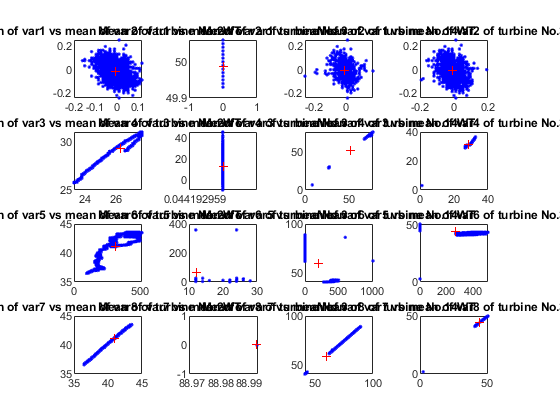

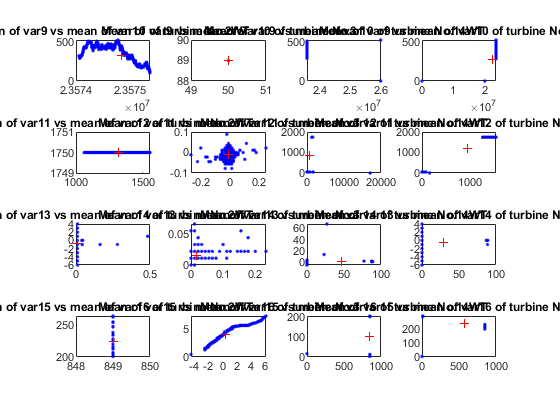

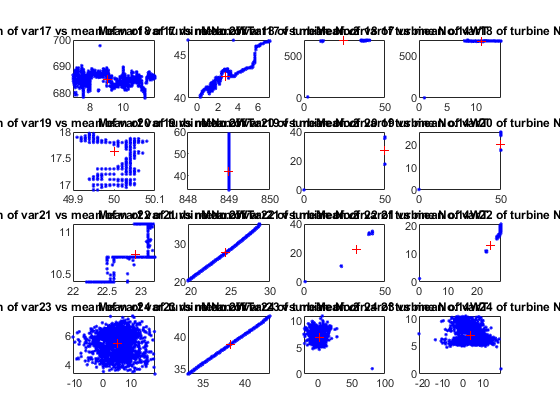

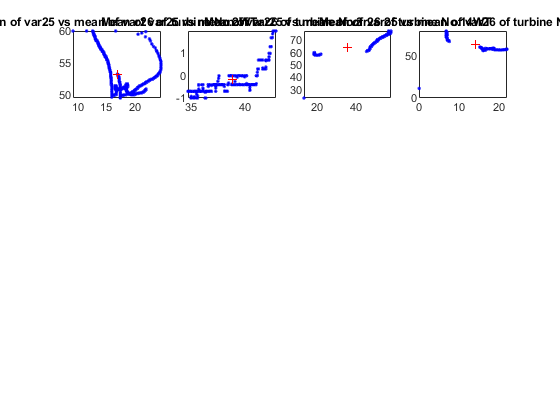

nWTs = numel(turbine_idx);

% Define rWTs vector storing no of observations (number of rows);
% cWTs vector storing no of variables (number of columns);
% meanWTs cell array storing mean values of feature data (mean value of each column);
% minWTs cell array storing minimum values of feature data (minimum value of each column);
% maxWTs cell array storing maximum values of feature data (maximum value of each column);
% stdWTs cell array storing standard deviation values of feature data
% (standard deviation value of each column) of all turbines' dataset;
rWTs = zeros(nWTs, 1);
cWTs = zeros(nWTs, 1);
meanWTs = cell(nWTs, 1);
minWTs = cell(nWTs, 1);
maxWTs = cell(nWTs, 1);
stdWTs = cell(nWTs, 1);

for k=1:nWTs
    [rWTs(k), cWTs(k)] = size(X{k});
    meanWTs{k} = mean(X{k});
    minWTs{k} = min(X{k});
    maxWTs{k} = max(X{k});
    stdWTs{k} = std(X{k});
end

% Plots of data and means

subplot_idx = reshape(1:16, 4, 4)';
count = 1;
enough = false;
for i=0:4:28
    figure;
    for r=1:4
        if (count > 27 || count + 1 > 27)
            enough = true;
            break
        end
        for k=1:nWTs
            subplot(4,nWTs,subplot_idx(r,k));
            plot(X{k}(:,count), X{k}(:,count+1), '.b'), hold on;
            plot(meanWTs{k}(count), meanWTs{k}(count+1), 'r+'), hold off;
            title_text = sprintf('Mean of var%d vs mean of var%d of turbine %s', count, count+1, turbine_idx{k});
            title(title_text);
        end
        count = count + 2;
    end
    if (enough)
        break
    end
end 

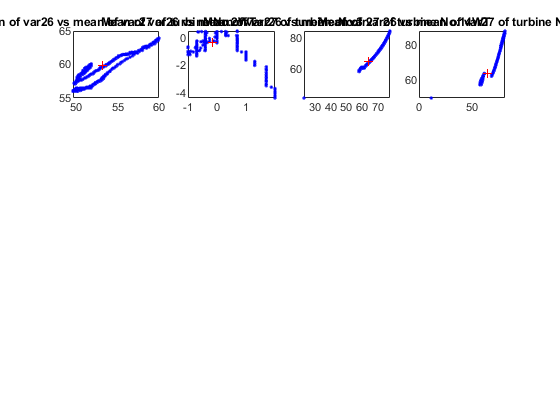


figure;
for k = 1:4
    subplot(4,nWTs,k);
    plot(X{k}(:,26), X{k}(:,26+1), '.b'), hold on;
    plot(meanWTs{k}(26), meanWTs{k}(26+1), 'r+'), hold off;
    title_text = sprintf('Mean of var%d vs mean of var%d of turbine %s', 26, 26+1, turbine_idx{k});
    title(title_text);
end

## Decision Making on fault and redundant data removal

Decision has been made to exclude the entire dataset belonging to the turbine No.3 (which is X{2}) due to fault data, and to also remove the last variable var28 of the dataset belonging to turbine No.2WT (which is X{1}(:,end)) due to redundancy and inconsistency.

Explanation on the decisions has been discussed in the report.

Z = {X{1}(:,1:end-1); X{3}; X{4}};

### Univariate analysis

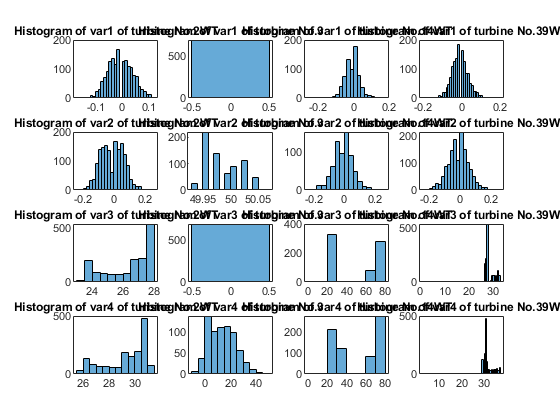

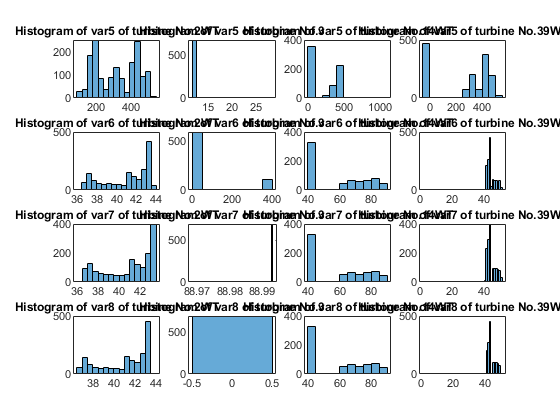

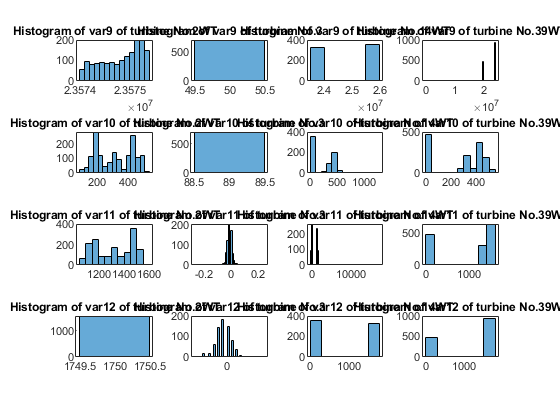

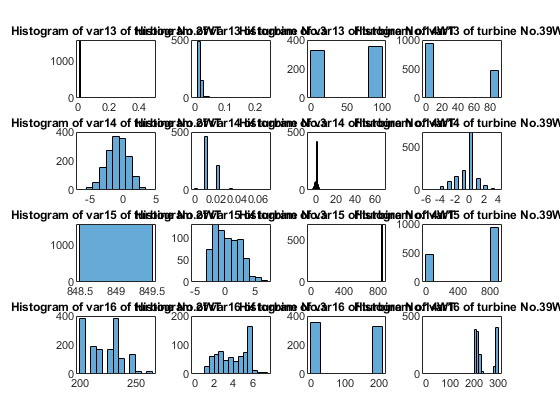

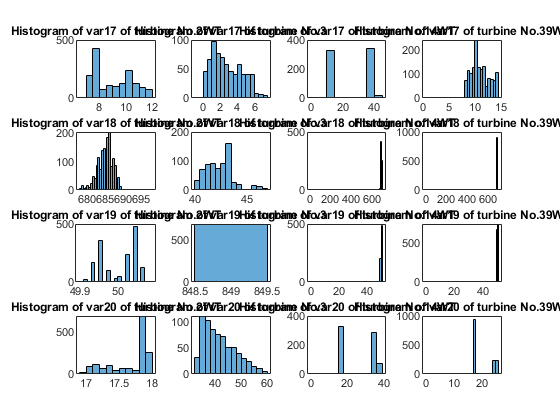

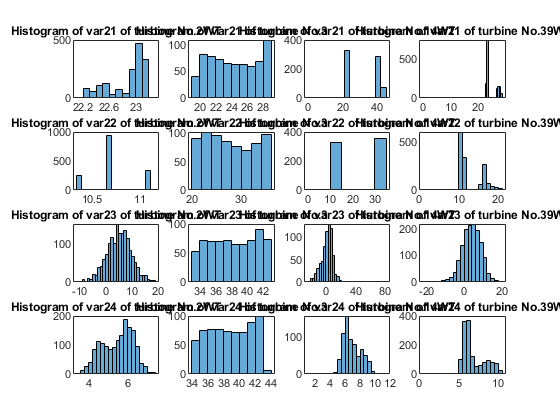

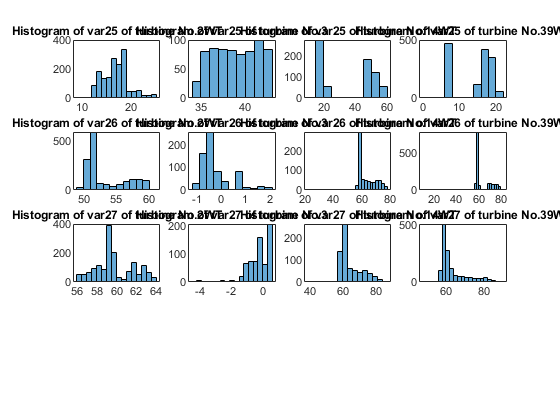

% Data distribution
subplot_idx = reshape(1:16, 4, 4)';
count = 1;
enough = false;
for i=0:4:28
    figure;
    for r=1:4
        if (count > 27 || count + 1 > 27)
            enough = true;
            break
        end
        for k=1:nWTs
            subplot(4,nWTs,subplot_idx(r,k));
            histogram(X{k}(:,count));
            title_text = sprintf('Histogram of var%d of turbine %s', count, turbine_idx{k});
            title(title_text);
        end
        count = count + 1;
    end
    if (enough)
        if (count == 27)
            for k=1:nWTs
            subplot(4,nWTs,subplot_idx(r,k));
            histogram(X{k}(:,count));
            title_text = sprintf('Histogram of var%d of turbine %s', count, turbine_idx{k});
            title(title_text);
            end
        end
        break
    end
end

### Multivariate analysis

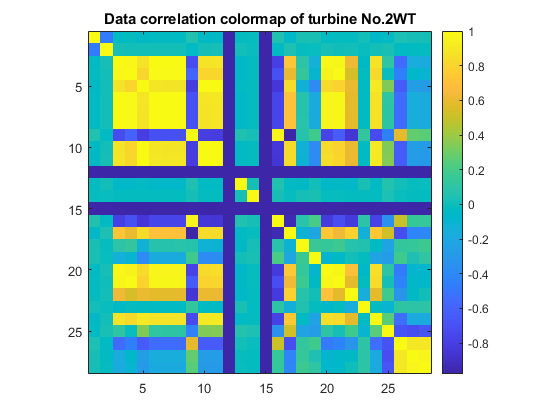

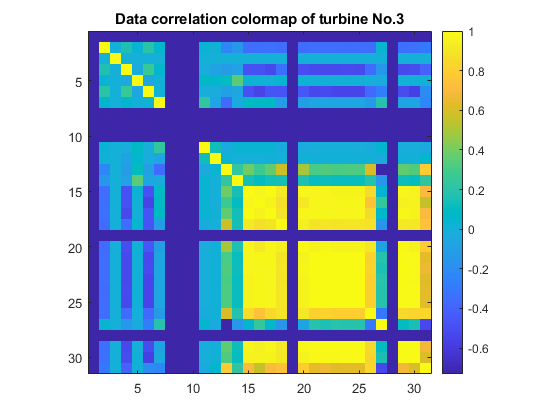

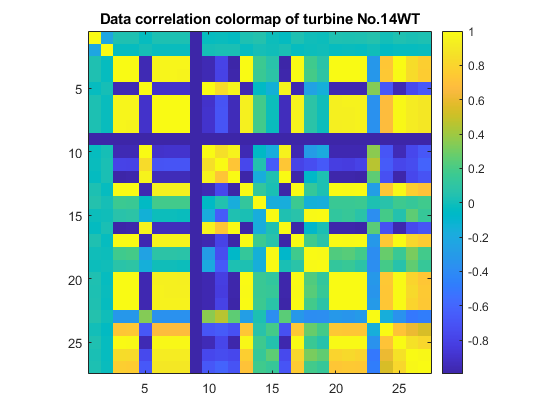

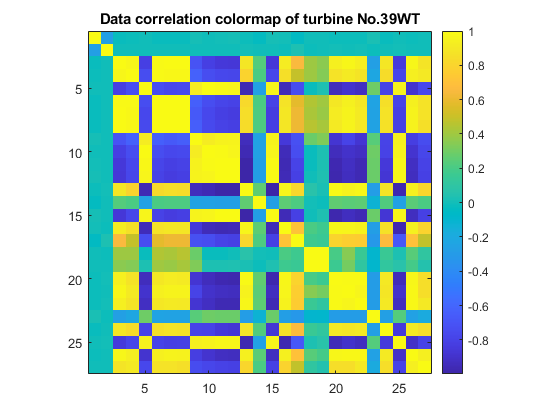

% Correlation between the features for each wind-turbine
Xcorr = cell(nWTs, 1);
for k=1:nWTs
    Xcorr{k} = corr(X{k});
    figure;
    imagesc(Xcorr{k}),colorbar;
    axis equal;
    axis tight;
    title_text = sprintf('Data correlation colormap of turbine %s', turbine_idx{k});
    title(title_text);
end

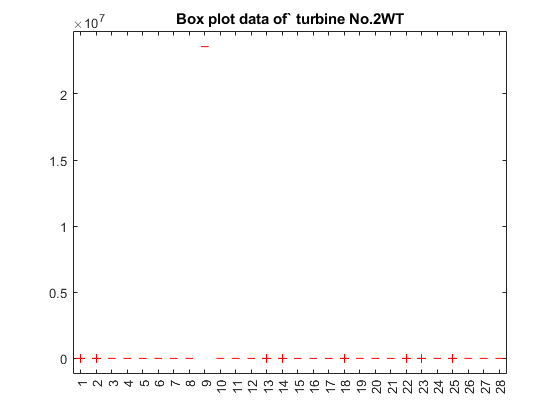

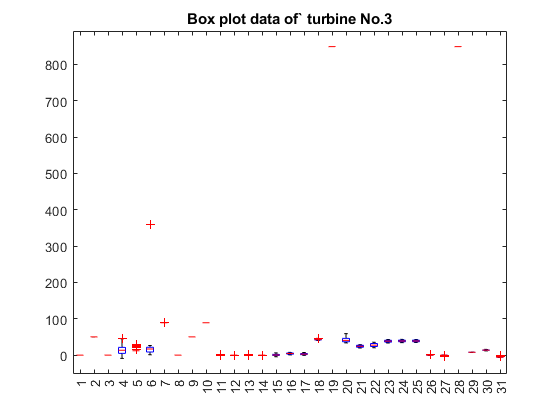

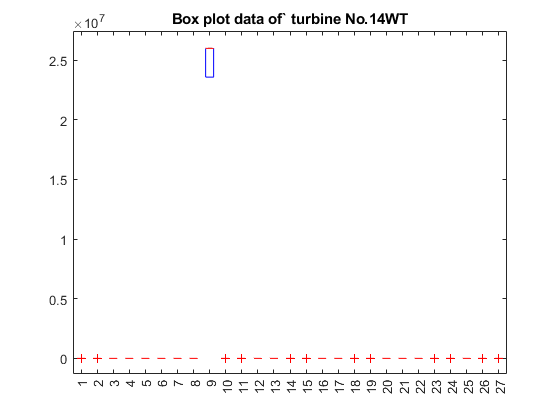

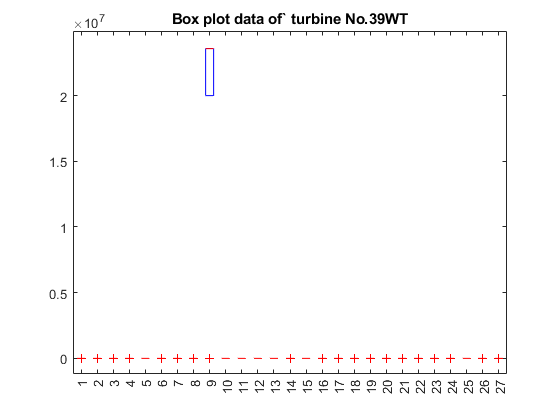


% Boxplot of each feature of the wind-turbine
for k=1:nWTs
    figure;
    boxplot(X{k});
    title_text = sprintf('Box plot data of` turbine %s', turbine_idx{k});
    title(title_text);
end


% Scatterplot matrix for all the sensors from each wind-turbine
for k=1:nWTs
    figure;
    plotmatrix(X{k});
    title_text = sprintf('Scatter plot matrix of` turbine %s', turbine_idx{k});
    title(title_text);
end


